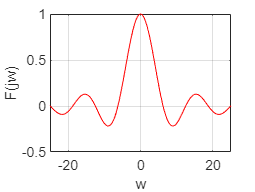

scale=0.5;
E=1;
N=500;
K=1000;
t_begin=-1; t_end=1; w_begin=-8*pi; w_end=8*pi;
t=linspace(t_begin,t_end,N);
w=linspace(w_begin,w_end,K);
y=E*rectpuls(t,2*scale);
exponent=exp((-1j)*(transpose(w)*t));
F_matrix=(t_end-t_begin)/N*exponent*transpose(y);
plot(w,F_matrix,'r-'); grid on;  xlabel('w');  ylabel('F(jw)');

exponent2_temp=transpose(exponent);
t1=clock;
f2=(w_end-w_begin)/2/pi/K*exponent2_temp*F_matrix;
t2=clock;
plot(t,y,'r-');  grid on; 
hold on;
xlabel('t'); ylabel('f');
plot(t,f2,'--b');

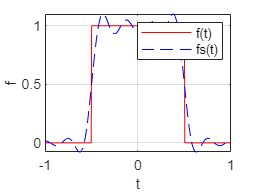

legend('f(t)','fs(t)'); 
hold off

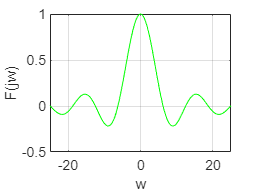

time_matrix=etime(t2,t1);    %matrix



t1=clock;
for k=1:K
    for n=1:N  
        if(n-1>0)
            F_for(k,n)=F_for(k,n-1)+(t_end-t_begin)/N*y(1,n)*exp(-1j*w(1,k)*t(1,n));
        else
            F_for(k,n)=(t_end-t_begin)/N*y(1,n)*exp(-1j*w(1,k)*t(1,n));
        end
    end
end                %DFT
t2=clock;
time_for=etime(t2,t1);
plot(w,F_for(:,N),'g-'); grid on; xlabel('w');  ylabel('F(jw)');

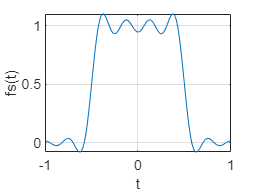

for n=1:N
    for  k=1:K 
        if(k-1>0)
            iF_for(n,k)=iF_for(n,k-1)+(w_end-w_begin)/2/pi/K*F_for(k,N)*exp(1j*w(1,k)*t(1,n));
        else
            iF_for(n,k)=(w_end-w_begin)/2/pi/K*F_for(k,N)*exp(1j*w(1,k)*t(1,n));
        end
    end
end            %IDFT
plot(t,iF_for(:,K));  grid on;  xlabel('t'); ylabel('fs(t)');      %for_loop

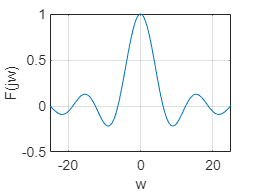





t1=clock;
for k=1:K
    F_vector(1,k)=(t_end-t_begin)/N*exp(-1j*w(1,k)*t)*transpose(y);
end            %DFT
t2=clock;
time_vector=etime(t2,t1);
plot(w,F_vector);  grid on; xlabel('w');  ylabel('F(jw)');

for n=1:N
    iF_vector(1,n)=(w_end-w_begin)/2/pi/K*exp(1j*t(1,n)*w)*transpose(F_vector);
end           %IDFT
plot(t,iF_vector);  grid on;  xlabel('t'); ylabel('fs(t)');             %vector

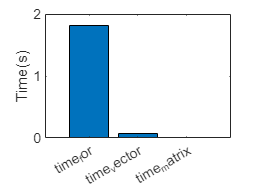



X = categorical({'time_for','time_vector','time_matrix'});
X = reordercats(X,{'time_for','time_vector','time_matrix'});
TIME = [time_for time_vector time_matrix];
bar(X,TIME); ylabel('Time(s)');